# 

# **Polynomial Regression (Quadratic) *****With Z-Matrix***** (Lec10) [In-Class]**

Fit a quadratic to the following data:

`x = [3 4 5 7 8 9 11 12]';`

`y = [40 88 110 200 290 347 510 625]';`

Determine the $r^2$ and $s_{\frac{y}{x}}$.

Use the least-squares fit to predict the value of y when x = 6.

Rounding a decimal number to four decimal places.

$r^2$ = ?

$s_{\frac{y}{x}}$ = ?

x = 6, y = ?

**Data**

x = [3 4 5 7 8 9 11 12]';
y = [40 88 110 200 290 347 510 625]';

**Plot data**

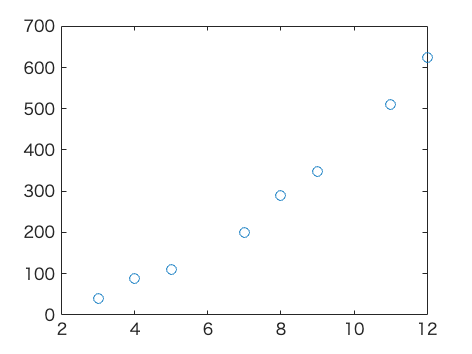

plot(x, y, 'o')

**Create Z matrix**

Z = [ones(size(y)), x, x.^2]

Z =      1     3     9
     1     4    16
     1     5    25
     1     7    49
     1     8    64
     1     9    81
     1    11   121
     1    12   144


**Solve for unknown parameters  a **


$$\begin{array}{l}
\left\lbrack {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrack \mathit{\mathbf{Z}}\right\rbrack \right\rbrack \left\lbrace a\right\rbrace =\left\lbrace {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrace \mathit{\mathbf{y}}\right\rbrace \right\rbrace \\
\left\lbrace a\right\rbrace ={\left\lbrack {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrack \mathit{\mathbf{Z}}\right\rbrack \right\rbrack }^{-1} \left\lbrace {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrace \mathit{\mathbf{y}}\right\rbrace \right\rbrace 
\end{array}$$


*(see as ****A****x = ****b****, in MATLAB as x*` = A \ b`*)*

**NOTE: **`\`* (left division operator) *is used to solve a system of linear equations in the form of $A\cdot x=b$.

a = (Z' * Z) \ (Z' * y)

a =    16.6925
   -3.0965
    4.4384


**Plot data and the best fitted curve**

xp = linspace(min(x), max(x), 100)

xp =     3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545    5.5455    5.6364    5.7273    5.8182    5.9091    6.0000    6.0909    6.1818    6.2727    6.3636    6.4545    6.5455    6.6364    6.7273    6.8182    6.9091    7.0000    7.0909    7.1818    7.2727    7.3636    7.4545


yp = a(1) + (a(2) .* xp) + (a(3) .* xp.^2)

yp =    47.3487   49.5249   51.7744   54.0972   56.4935   58.9630   61.5060   64.1223   66.8120   69.5750   72.4114   75.3211   78.3043   81.3607   84.4906   87.6938   90.9704   94.3203   97.7436  101.2402  104.8103  108.4536  112.1704  115.9605  119.8240  123.7608  127.7710  131.8545  136.0115  140.2417  144.5454  148.9224  153.3727  157.8965  162.4936  167.1640  171.9078  176.7250  181.6155  186.5794  191.6167  196.7273  201.9113  207.1687  212.4994  217.9034  223.3809  228.9317  234.5558  240.2534


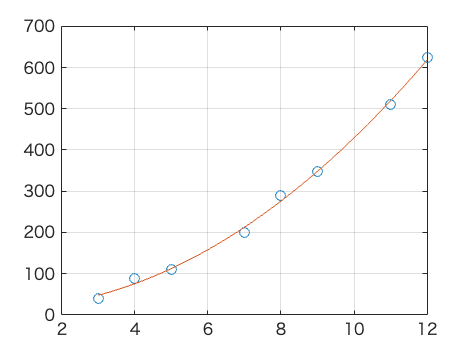

plot(x, y, 'o', xp, yp)
grid on

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

sr = sum((y - (Z*a)) .^ 2)

sr = 707.8754

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

st = sum((y - mean(y)).^2)

st = 3.0617e+05

**Compute  r2  (the coefficient of determination)**

r2 = 1 - (sr/st)

r2 = 0.9977

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(sr / (length(y) - 3))

syx = 11.8985

**Predict the value of y for the given x**

xtest = 6

xtest = 6

ytest = a(1) + (a(2) .* xtest) + (a(3) .* xtest.^2)

ytest = 157.8965